% LPF Butterworth IIR
clc
clear all;
close all;
fs = 10000;

wp=input('enter pass band frequency: ')

wp = 1000

ws=input('enter stop band frequency: ')

ws = 2000

deltap=input('enter pass band ripple: ')

deltap = 2

deltas=input('enter stop band ripple: ')

deltas = 3

omegap=2*tan(wp*pi/fs)/sqrt(1+tan(wp*pi/fs)^2)

omegap = 0.6180

omegas=2*tan(ws*pi/fs)/sqrt(1+tan(ws*pi/fs)^2)

omegas = 1.1756

den=log10(omegas/omegap)

den = 0.2792

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.8889

epsi=1/deltap^2-1

epsi = -0.7500

num=2*log10(delta/epsi)

num = 0.1476

order=ceil(num/den)

order = 1

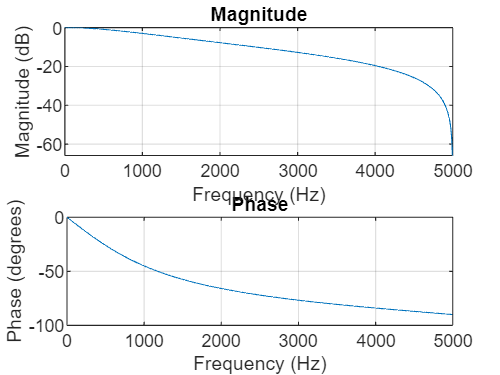


f1 = 500;
f2 = 2000;
N = 200;
t = 0:N-1;
x = sin(2*pi*f1*t/fs) + 2*sin(2*pi*f2*t/fs);
% Design a low-pass Butterworth filter
cutoff_frequency = 1000; % Adjust as needed
[b, a] = butter(order, cutoff_frequency/(fs/2), 'low');
freqz(b,a,1000,fs)

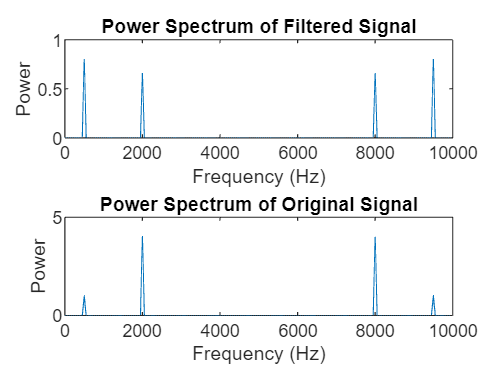


% Apply the filter to the signal
filtered_signal = filter(b, a, x);

% Compute the power spectrum of the filtered signal
xf_filtered = 2 * abs(fft(filtered_signal))/N;
two_power_filtered = xf_filtered .* xf_filtered;
f_filtered = (0:N-1) * fs/N;

% Plot the original and filtered power spectra
figure;
subplot(2,1,1);
plot(f_filtered, two_power_filtered);
title('Power Spectrum of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(2,1,2);
xf = 2 * abs(fft(x))/N;
two_power = xf .* xf;
f = (0:N-1) * fs/N;
plot(f, two_power);
title('Power Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

% HPF Butterworth IIR
clc
clear all;
close all;
fs = 10000;
f1 = 500;
f2 = 2000;
N = 200;
t = 0:N-1;
x = sin(2*pi*f1*t/fs) + 2*sin(2*pi*f2*t/fs);
wp=input('enter pass band frequency: ')
ws=input('enter stop band frequency: ')
deltap=input('enter pass band ripple: ')
deltas=input('enter stop band ripple: ')
omegap=2*tan(wp*pi/fs)/sqrt(1+tan(wp*pi/fs)^2)
omegas=2*tan(ws*pi/fs)/sqrt(1+tan(ws*pi/fs)^2)
den=log10(omegas/omegap)
delta=min(1/deltap^2-1,1/deltas^2-1)
epsi=1/deltap^2-1
num=2*log10(delta/epsi)
order=ceil(num/den)

% Design a low-pass Butterworth filter
cutoff_frequency = 1000; % Adjust as needed
[b, a] = butter(order, cutoff_frequency/(fs/2), 'high');
freqz(b,a,1000,fs)

% Apply the filter to the signal
filtered_signal = filter(b, a, x);

% Compute the power spectrum of the filtered signal
xf_filtered = 2 * abs(fft(filtered_signal))/N;
two_power_filtered = xf_filtered .* xf_filtered;
f_filtered = (0:N-1) * fs/N;

% Plot the original and filtered power spectra
figure;
subplot(2,1,1);
plot(f_filtered, two_power_filtered);
title('Power Spectrum of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(2,1,2);
xf = 2 * abs(fft(x))/N;
two_power = xf .* xf;
f = (0:N-1) * fs/N;
plot(f, two_power);
title('Power Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

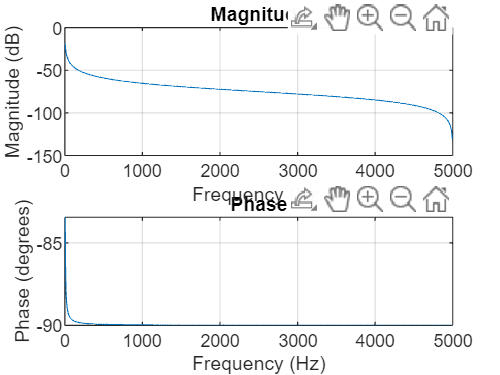

%band pass Butterworth IIR
clc;
clear all;
close all;

fs = 10000;
f1 = 500;
f2 = 2000;
N = 200;
t = 0:N-1;
x = sin(2*pi*f1*t/fs) + 2*sin(2*pi*f2*t/fs);

wp1 = input('Enter lower pass band frequency: ');
wp2 = input('Enter upper pass band frequency: ');
ws1 = input('Enter lower stop band frequency: ');
ws2 = input('Enter upper stop band frequency: ');
deltap = input('Enter pass band ripple: ');
deltas = input('Enter stop band ripple: ');

omegap1 = 2 * tan(wp1*pi/fs) / sqrt(1 + tan(wp1*pi/fs)^2);
omegap2 = 2 * tan(wp2*pi/fs) / sqrt(1 + tan(wp2*pi/fs)^2);
omegas1 = 2 * tan(ws1*pi/fs) / sqrt(1 + tan(ws1*pi/fs)^2);
omegas2 = 2 * tan(ws2*pi/fs) / sqrt(1 + tan(ws2*pi/fs)^2);

den = log10((omegas2 * omegas1) / (omegap2 * omegap1));
delta = min(1/deltap^2 - 1, 1/deltas^2 - 1);
epsi = 1/deltap^2 - 1;
num = 2 * log10(delta/epsi);
order = ceil(num/den);

% Design a band-pass Butterworth filter
[b, a] = butter(order, [omegap1 omegap2]/(fs/2), 'bandpass');

% Plot the frequency response of the filter
figure;
freqz(b, a, 1000, fs);

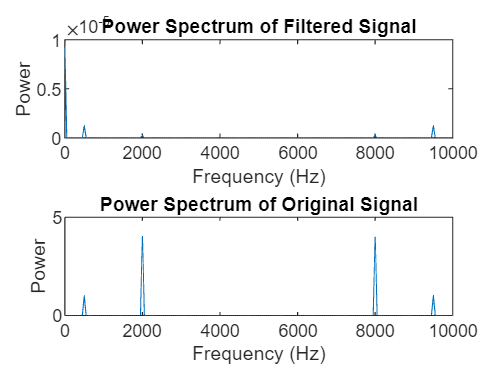


% Apply the filter to the signal
filtered_signal = filter(b, a, x);

% Compute the power spectrum of the filtered signal
xf_filtered = 2 * abs(fft(filtered_signal))/N;
two_power_filtered = xf_filtered .* xf_filtered;
f_filtered = (0:N-1) * fs/N;

% Plot the original and filtered power spectra
figure;
subplot(2,1,1);
plot(f_filtered, two_power_filtered);
title('Power Spectrum of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(2,1,2);
xf = 2 * abs(fft(x))/N;
two_power = xf .* xf;
f = (0:N-1) * fs/N;
plot(f, two_power);
title('Power Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

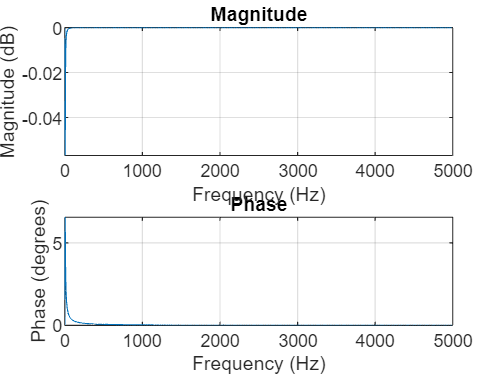

%band stop Butterworth IIR
clc;
clear all;
close all;

fs = 10000;
f1 = 500;
f2 = 2000;
N = 200;
t = 0:N-1;
x = sin(2*pi*f1*t/fs) + 2*sin(2*pi*f2*t/fs);

wp1 = input('Enter lower pass band frequency: ');
wp2 = input('Enter upper pass band frequency: ');
ws1 = input('Enter lower stop band frequency: ');
ws2 = input('Enter upper stop band frequency: ');
deltap = input('Enter pass band ripple: ');
deltas = input('Enter stop band ripple: ');

omegap1 = 2 * tan(wp1*pi/fs) / sqrt(1 + tan(wp1*pi/fs)^2);
omegap2 = 2 * tan(wp2*pi/fs) / sqrt(1 + tan(wp2*pi/fs)^2);
omegas1 = 2 * tan(ws1*pi/fs) / sqrt(1 + tan(ws1*pi/fs)^2);
omegas2 = 2 * tan(ws2*pi/fs) / sqrt(1 + tan(ws2*pi/fs)^2);

den = log10((omegas2 * omegas1) / (omegap2 * omegap1));
delta = min(1/deltap^2 - 1, 1/deltas^2 - 1);
epsi = 1/deltap^2 - 1;
num = 2 * log10(delta/epsi);
order = ceil(num/den);

% Design a band-pass Butterworth filter
[b, a] = butter(order, [omegap1 omegap2]/(fs/2), 'stop');

% Plot the frequency response of the filter
figure;
freqz(b, a, 1000, fs);

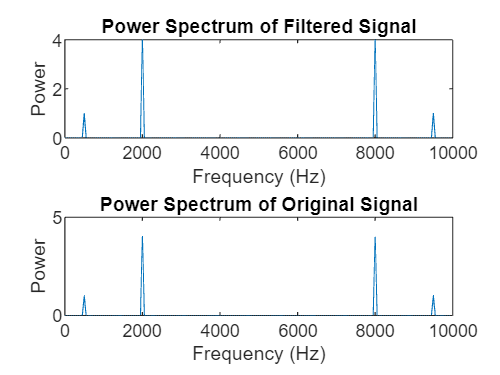


% Apply the filter to the signal
filtered_signal = filter(b, a, x);

% Compute the power spectrum of the filtered signal
xf_filtered = 2 * abs(fft(filtered_signal))/N;
two_power_filtered = xf_filtered .* xf_filtered;
f_filtered = (0:N-1) * fs/N;

% Plot the original and filtered power spectra
figure;
subplot(2,1,1);
plot(f_filtered, two_power_filtered);
title('Power Spectrum of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power');

subplot(2,1,2);
xf = 2 * abs(fft(x))/N;
two_power = xf .* xf;
f = (0:N-1) * fs/N;
plot(f, two_power);
title('Power Spectrum of Original Signal');
xlabel('Frequency (Hz)');
ylabel('Power');